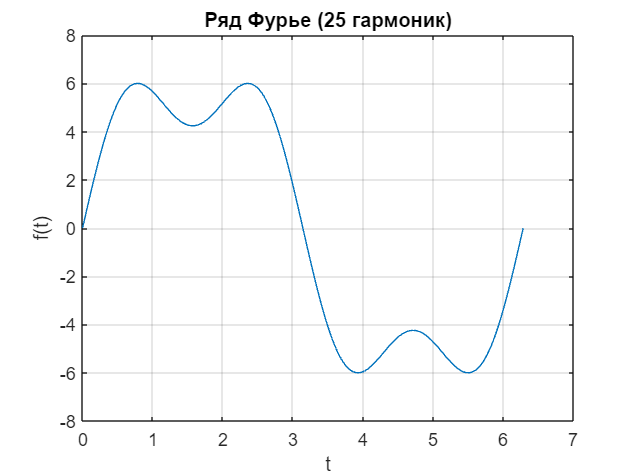

clear;
% Разложение функции в Фурье

t = linspace(0, 2*pi, 1000);
n = 1:3;
coeffs = (1 - (-1).^n)./n;
y = (10/pi) * sum(sin(n'*t) .* coeffs', 1);

figure;
plot(t, y);
title('Ряд Фурье (25 гармоник)');
xlabel('t'); ylabel('f(t)');
grid on;



% Что-то тут про генератор

n_harm = 3; % Число гармоник
harmonics = [1, 3, 5]; % Нечётные частоты

G = zeros(2*n_harm, 2*n_harm);
for k = 1:n_harm
    idx = 2*k-1 : 2*k;
    G(idx, idx) = [0, harmonics(k)*pi(); -harmonics(k)*pi(), 0];
end

disp('Матрица Gamma:'); disp(G);

Матрица Gamma:
         0    3.1416         0         0         0         0
   -3.1416         0         0         0         0         0
         0         0         0    9.4248         0         0
         0         0   -9.4248         0         0         0
         0         0         0         0         0   15.7080
         0         0         0         0  -15.7080         0



disp(['Размер: ', num2str(size(G))]);

Размер: 6  6



w0 = [1 1 1 1 1 1]';

% что-то про Cz и Dz и вообще систему
A = [3 0; 0 1];
B = [1; 1];

%Dz = (10/pi) * [0 2 0 0.666 0 0.4];
Dz = [0 2 0 0.666 0 0.4];
Cz = [-1 0];


% Находим К1
disp('Собственные числа А');

Собственные числа А


disp(eig(A));

     1
     3



u = [B A*B];
r_u = rank(u);
disp('Ранг U');

Ранг U


disp(r_u);

     2




G_k1 = [0 -1; 1 -2];
Y_k1 = [1 1];

cvx_begin sdp
variable P_k1(2, 2)
A * P_k1 - P_k1 * G_k1 == B * Y_k1;
%P_k1 >= 0;
cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



K1 = -Y_k1 * pinv(P_k1);
%d = det(P_k1);
new_k1 = A + B * K1;
e = eig(new_k1);
disp('K1');

K1


disp(K1);

    -8     2



%disp(d);
disp(e);

  -1.0000 + 0.0000i
  -1.0000 - 0.0000i




% Находим K2

cvx_begin sdp

variable P2(2, 6)
variable Y2(1, 6)
P2 * G - A * P2 == B * Y2;
Cz * P2 + Dz == 0;
cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



disp('P_2');

P_2


disp(P2);

         0    2.0000         0    0.6660         0    0.4000
   -1.1561    2.3680   -0.1398    0.6808   -0.0507    0.4032



disp('Y_2');

Y_2


disp(Y2);

   -6.2832   -6.0000   -6.2769   -1.9980   -6.2832   -1.2000




K2 = Y2 - K1 * P2;
disp('K_2');

K_2


disp(K2);

   -3.9710    5.2640   -5.9974    1.9683   -6.1817    1.1935



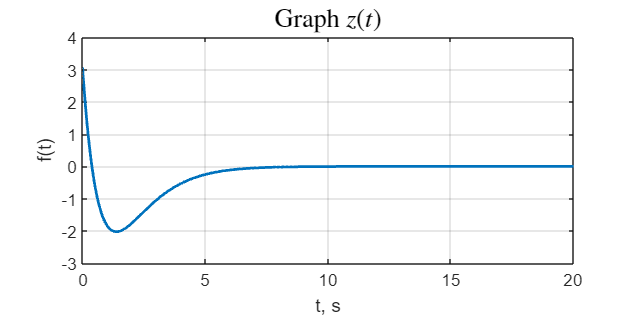


% что-то про симуляцию

open_system('task_4_sim');
set_param('task_4_sim/w', 'VariableName', 'w');
set_param('task_4_sim/z', 'VariableName', 'z');
set_param('task_4_sim/g', 'VariableName', 'g');
out = sim('task_4_sim');

figure('Position', [100 100 800 400])
plot(out.z,'-', 'LineWidth',1.5);
grid()
title('Graph $z(t)$','Interpreter','latex',  'FontSize', 14)
%legend('$w_1(t)$', '$w_2(t)$','$w_3(t)$','$w_4(t)$', '$\hat{w}_1(t)$', '$\hat{w}_2(t)$', '$\hat{w}_3(t)$','$\hat{w}_4(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')

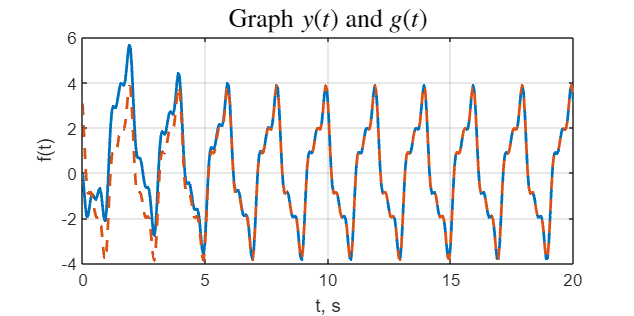



figure('Position', [100 100 800 400])
plot(out.x.Time, out.x.Data(:,1),'-', 'LineWidth',1.5);
%plot(out.x,'-', 'LineWidth',1.5);
hold on
plot(out.g,'--', 'LineWidth',1.5);
grid()
title('Graph $y(t)$ and $g(t)$','Interpreter','latex',  'FontSize', 14)
%legend('$w_1(t)$', '$w_2(t)$','$w_3(t)$','$w_4(t)$', '$\hat{w}_1(t)$', '$\hat{w}_2(t)$', '$\hat{w}_3(t)$','$\hat{w}_4(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
hold off